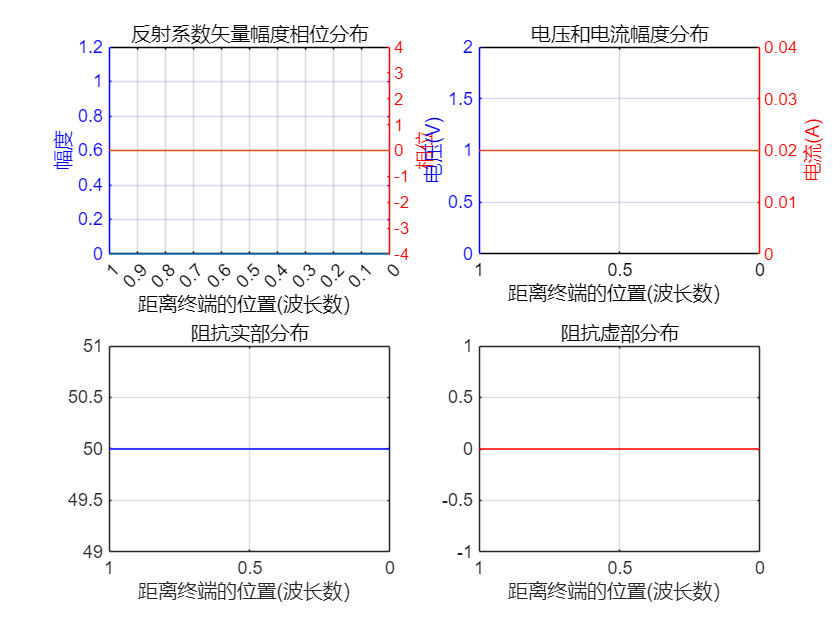

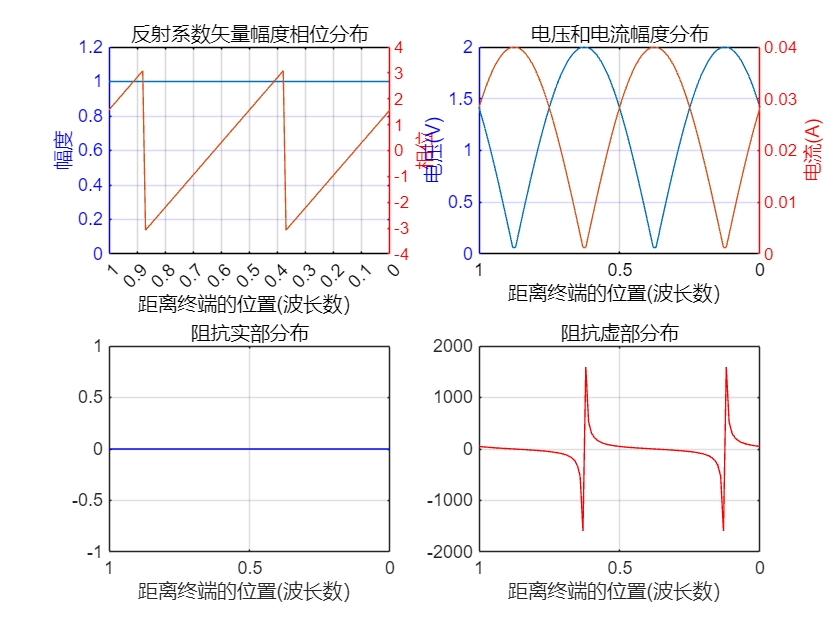

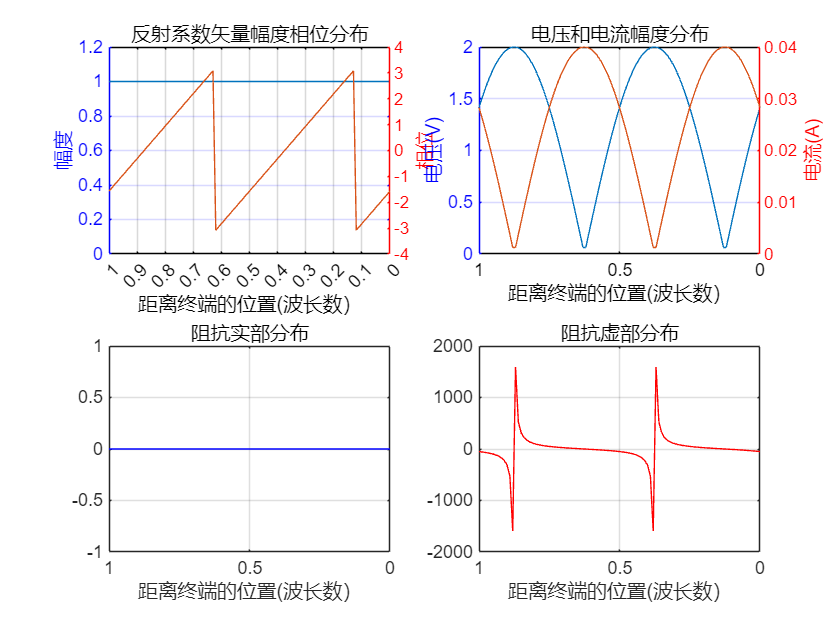

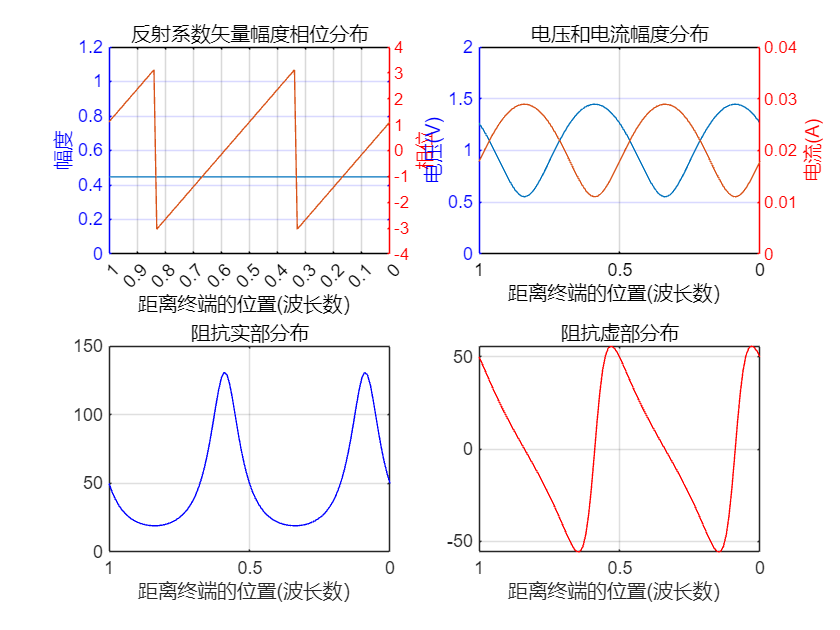

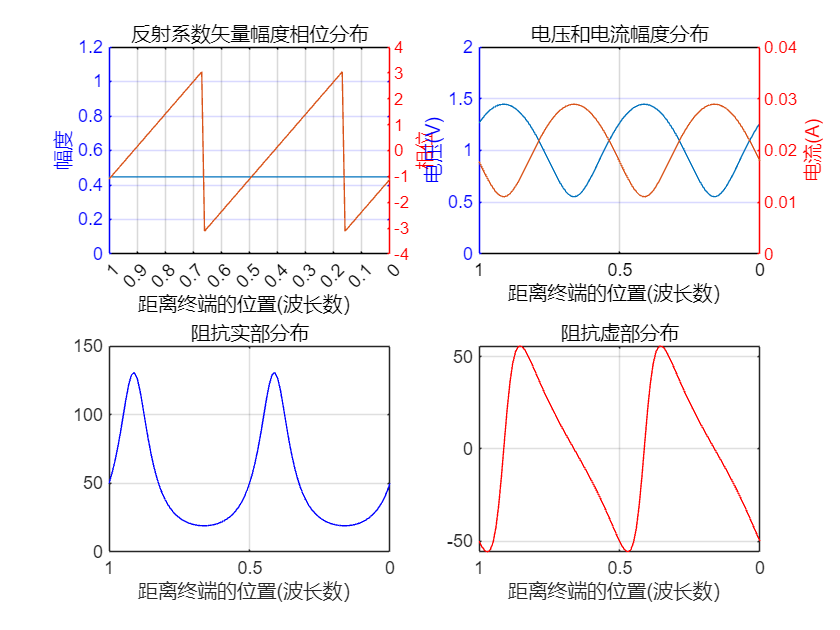

%%%%%%%%%%%%%%%%%%%%
%实验一 传输线特性的计算机仿真分析
%%%%%%%%%%%%%%%%%%%
clear;
Eg=2;
Zg=50;
Z0=50;
lamuta=0.3;
bata=2*pi/lamuta;
z=0:0.01:1;     %归一化
Zl=[50,50*1i,-50*1i,50+50*1i,50-50*1i];
for k=1:5
    figure(k);
    subplot(2,2,1);
    reflection_coefficient(Zl(1,k),Z0,lamuta,bata,z);
    subplot(2,2,2);
    transmission_lines_U_I(Zl(1,k),Z0,lamuta,bata,z,Eg,Zg);
    subplot(2,2,3);
    input_R_real(Zl(1,k),Z0,lamuta,bata,z);
    subplot(2,2,4);
    input_R_imag(Zl(1,k),Z0,lamuta,bata,z);
end


%--------传输线上电压反射系数-------%
function reflection_coefficient(Zl,Z0,lamuta,bata,z)
T=(Zl-Z0)/(Zl+Z0)*exp(-2*1i*bata*z*lamuta); %反射系数
AX=plotyy(z,abs(T),z,angle(T));
set(AX(1),'Xcolor','k','Ycolor','b');       %设置x轴为黑色、左y轴刻度字体为红色；
set(AX(2),'Xcolor','k','Ycolor','r');       %设置x轴、右y轴刻度字体为蓝色；
set(AX,'Xlim',[0,1],'xtick',0:0.1:1);       %设置x轴数据范围（0,1），刻度显示（0 0.1 0.2...1）
set(AX(1),'ylim',[0,1.2],'ytick',0:0.2:1.2);%设置左y轴数据范围（0,1），刻度显示（0,0.2,0.4...1）
set(AX(2),'ylim',[-4,4],'ytick',-4:1:4);    %设置右y轴数据范围（-4,4）,刻度显示（-4,-3...4）
set(get(AX(1),'Ylabel'),'string','幅度');
set(get(AX(2),'Ylabel'),'string','相位');
title('反射系数矢量幅度相位分布');
set(AX,'Xdir','reverse');                   %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
end

%------传输线上电压和电流幅度------%
function transmission_lines_U_I(Zl,Z0,lamuta,bata,z,Eg,Zg)
Zinl=Z0*((Zl+1i*Z0*tan(bata*lamuta))/(Z0+1i*Zl*tan(bata*lamuta)));  %首先计算始端处阻抗
Vin=Eg*Zinl/(Zg+Zinl);                                              %接着计算出输入端电压
Tin=(Zl-Z0)/(Zl+Z0)*exp(-2*1i*bata*lamuta);                         %计算出输入端的反射系数               
A1=Vin/(exp(1j*bata*lamuta)*(1+Tin));                               %然后计算出A1
T=(Zl-Z0)/(Zl+Z0)*exp(-2*1i*bata*z*lamuta);   
U=A1*exp(1j*bata*z*lamuta).*(1+T);                                  %计算出任意点处的电压
I=A1/Z0*exp(1j*bata*z*lamuta).*(1-T);                               %计算出任意点处的电流
subplot(2,2,2);
AX=plotyy(z,abs(U),z,abs(I));
set(AX(1),'Xcolor','k','Ycolor','b');       %设置x轴为黑色、左y轴刻度字体为红色；
set(AX(2),'Xcolor','k','Ycolor','r');       %设置x轴、右y轴刻度字体为蓝色；
set(AX(1),'ylim',[0,Eg],'ytick',0:Eg/4:Eg);
set(AX(2),'ylim',[0,Eg/Z0],'ytick',0:Eg/4/Z0:Eg/Z0);
set(get(AX(1),'Ylabel'),'string','电压(V)');
set(get(AX(2),'Ylabel'),'string','电流(A)');
title('电压和电流幅度分布');
set(AX,'Xdir','reverse');                   %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
end

%------输入阻抗实部的分布------%
function input_R_real(Zl,Z0,lamuta,bata,z)
Zinl=Z0*((Zl+1i*Z0*tan(bata*z*lamuta))./(Z0+1i*Zl*tan(bata*z*lamuta)));
R_Zinl=real(Zinl);
plot(z,R_Zinl,'b');
title('阻抗实部分布');
set(gca,'Xdir','reverse');                  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
end

%------输入阻抗实部的分布------%
function input_R_imag(Zl,Z0,lamuta,bata,z)
Zinl=Z0*((Zl+1i*Z0*tan(bata*z*lamuta))./(Z0+1i*Zl*tan(bata*z*lamuta)));
I_Zinl=imag(Zinl); 
if((max(I_Zinl))<1e-6||(max(I_Zinl))>1e10)
    I_Zinl = I_Zinl*0;
end
plot(z,I_Zinl,'r');
title('阻抗虚部分布');
set(gca,'Xdir','reverse');                  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
end